% =========================================================================
% SCRIPT : EXTRACT_BEST_PARAMS_PER_K (Version Finale)
% Objectif : Trouver les meilleurs paramètres, exporter Excel et Graphiques
% =========================================================================

clear; clc;

%% 1. PARAMÈTRES ET CHEMINS
% <-- MODIFIEZ CECI SI BESOIN
% dossier_mere = 'E:\Data\Aurelie\analysis\March2026\nocues\assembly\test\411582\';
dossier_mere = 'E:\Data\Aurelie\analysis\March2026\nocues\assembly\testparametre\444119';
top_n_plot = 10; % Nombre de tests à afficher sur le 2ème graphique (le Top N)

%% 2. POIDS DES CRITÈRES (Total = 1.00)
w_sil        = 0.30;  % sil all clusters (séparation mathématique)
w_assemblies = 0.20;  % Assemblies (quantité) 
w_recall     = 0.20;  % recall (SClok)
w_sce        = 0.15;  % SCE_Purity
w_cell       = 0.15;  % cell_Purity

%% 3. RECHERCHE DES FICHIERS RESULTS.MAT
fprintf('Recherche des fichiers results.mat...\n');

Recherche des fichiers results.mat...


tous_les_fichiers = dir(fullfile(dossier_mere, '**', 'results.mat'));
if isempty(tous_les_fichiers), error('Aucun fichier results.mat trouvé.'); end
fprintf('%d fichiers trouvés. Analyse en cours...\n\n', length(tous_les_fichiers));

783 fichiers trouvés. Analyse en cours...




%% 4. EXTRACTION DES DONNÉES (Métriques + Hyperparamètres)
ResultsByK = struct();
h_wait = waitbar(0, 'Extraction des données...', 'Name', 'Progression');

for i = 1:length(tous_les_fichiers)
    matFilePath = fullfile(tous_les_fichiers(i).folder, tous_les_fichiers(i).name);
    parts = strsplit(tous_les_fichiers(i).folder, filesep);
    
    if length(parts) >= 2
        kFolderName = parts{end};         % ex: 'k5'
        paramFolderName = parts{end-1};   % ex: 'test_1'
    else
        continue;
    end
    k_num_str = regexp(kFolderName, '\d+', 'match');
    if isempty(k_num_str), continue; end
    current_k = str2double(k_num_str{1});
    
    try
        % Chargement sécurisé
        vars_to_load = {'NClOK', 'NRace', 'NRaceOK', 'mean_sClOK', 'mean_Event_Purity', ...
                        'mean_Cellular_Fidelity', 'opts', 'MinPeakDistancesce', ...
                        'MinPeakDistance', 'threshold_peak', 'synchronous_frames', ...
                        'sce_n_cells_threshold', 'SG_window'};
        available_vars = who('-file', matFilePath);
        vars_to_load = intersect(vars_to_load, available_vars);
        data = load(matFilePath, vars_to_load{:});
        
        % --- MÉTRIQUES ---
        if isfield(data, 'mean_sClOK') && ~isnan(data.mean_sClOK), current_sil = data.mean_sClOK; else continue; end
        if isfield(data, 'NClOK') && ~isnan(data.NClOK), current_assemblies = data.NClOK; else current_assemblies = 0; end
        if isfield(data, 'NRaceOK') && isfield(data, 'NRace') && data.NRace > 0, current_recall = (data.NRaceOK / data.NRace) * 100; else current_recall = 0; end
        if isfield(data, 'mean_Event_Purity') && ~isnan(data.mean_Event_Purity), current_sce_purity = data.mean_Event_Purity; else current_sce_purity = 0; end
        if isfield(data, 'mean_Cellular_Fidelity') && ~isnan(data.mean_Cellular_Fidelity), current_cell_purity = data.mean_Cellular_Fidelity; else current_cell_purity = 0; end
        
        % --- PARAMÈTRES (opts) ---
        c_DistSce = NaN; c_Dist = NaN; c_Thresh = NaN; c_Sync = NaN; c_SceN = NaN; c_SG = NaN;
        if isfield(data, 'opts')
            if isfield(data.opts, 'MinPeakDistancesce'), c_DistSce = data.opts.MinPeakDistancesce; end
            if isfield(data.opts, 'MinPeakDistance'), c_Dist = data.opts.MinPeakDistance; end
            if isfield(data.opts, 'threshold_peak'), c_Thresh = data.opts.threshold_peak; end
            if isfield(data.opts, 'synchronous_frames'), c_Sync = data.opts.synchronous_frames; end
            if isfield(data.opts, 'sce_n_cells_threshold'), c_SceN = data.opts.sce_n_cells_threshold; end
            if isfield(data.opts, 'SG_window'), c_SG = data.opts.SG_window; end
        end
        
        % Création de la structure pour ce K
        k_str = sprintf('K_%d', current_k);
        if ~isfield(ResultsByK, k_str)
            ResultsByK.(k_str) = struct('ParamFolder', {{}}, 'Paths', {{}}, ...
                'sil_all_clusters', [], 'Assemblies', [], 'recall', [], 'SCE_Purity', [], 'cell_Purity', [], ...
                'DistSce', [], 'Dist', [], 'Thresh', [], 'Sync', [], 'SceNCells', [], 'SGWin', []);
        end
        
        % Stockage
        ResultsByK.(k_str).ParamFolder{end+1} = paramFolderName;
        ResultsByK.(k_str).Paths{end+1} = tous_les_fichiers(i).folder;
        ResultsByK.(k_str).sil_all_clusters(end+1) = current_sil;
        ResultsByK.(k_str).Assemblies(end+1) = current_assemblies;
        ResultsByK.(k_str).recall(end+1) = current_recall;
        ResultsByK.(k_str).SCE_Purity(end+1) = current_sce_purity;
        ResultsByK.(k_str).cell_Purity(end+1) = current_cell_purity;
        ResultsByK.(k_str).DistSce(end+1) = c_DistSce;
        ResultsByK.(k_str).Dist(end+1) = c_Dist;
        ResultsByK.(k_str).Thresh(end+1) = c_Thresh;
        ResultsByK.(k_str).Sync(end+1) = c_Sync;
        ResultsByK.(k_str).SceNCells(end+1) = c_SceN;
        ResultsByK.(k_str).SGWin(end+1) = c_SG;
        
    catch exception
        fprintf('Erreur sur %s : %s\n', matFilePath, exception.message);
    end
    waitbar(i / length(tous_les_fichiers), h_wait, sprintf('Analyse : %d/%d', i, length(tous_les_fichiers)));
end

Erreur sur E:\Data\Aurelie\analysis\March2026\nocues\assembly\testparametre\444119\444119_220919_plane0_26_04_02_17_31_36\k15\results.mat : Operands to the logical AND (&&) and OR (||) operators must be convertible to logical scalar values. Use the ANY or ALL functions to reduce operands to logical scalar values.
Erreur sur E:\Data\Aurelie\analysis\March2026\nocues\assembly\testparametre\444119\444119_220919_plane0_26_04_02_17_43_57\k10\results.mat : Operands to the logical AND (&&) and OR (||) operators must be convertible to logical scalar values. Use the ANY or ALL functions to reduce operands to logical scalar values.
Erreur sur E:\Data\Aurelie\analysis\March2026\nocues\assembly\testparametre\444119\444119_220919_plane0_26_04_02_17_53_43\k15\results.mat : Operands to the logical AND (&&) and OR (||) operators must be convertible to logical scalar values. Use the ANY or ALL functions to reduce operands to logical scalar values.
Erreur sur E:\Data\Aurelie\analysis\March2026\nocues\as

ANALYSE POUR K_10 (76 tests analysés)


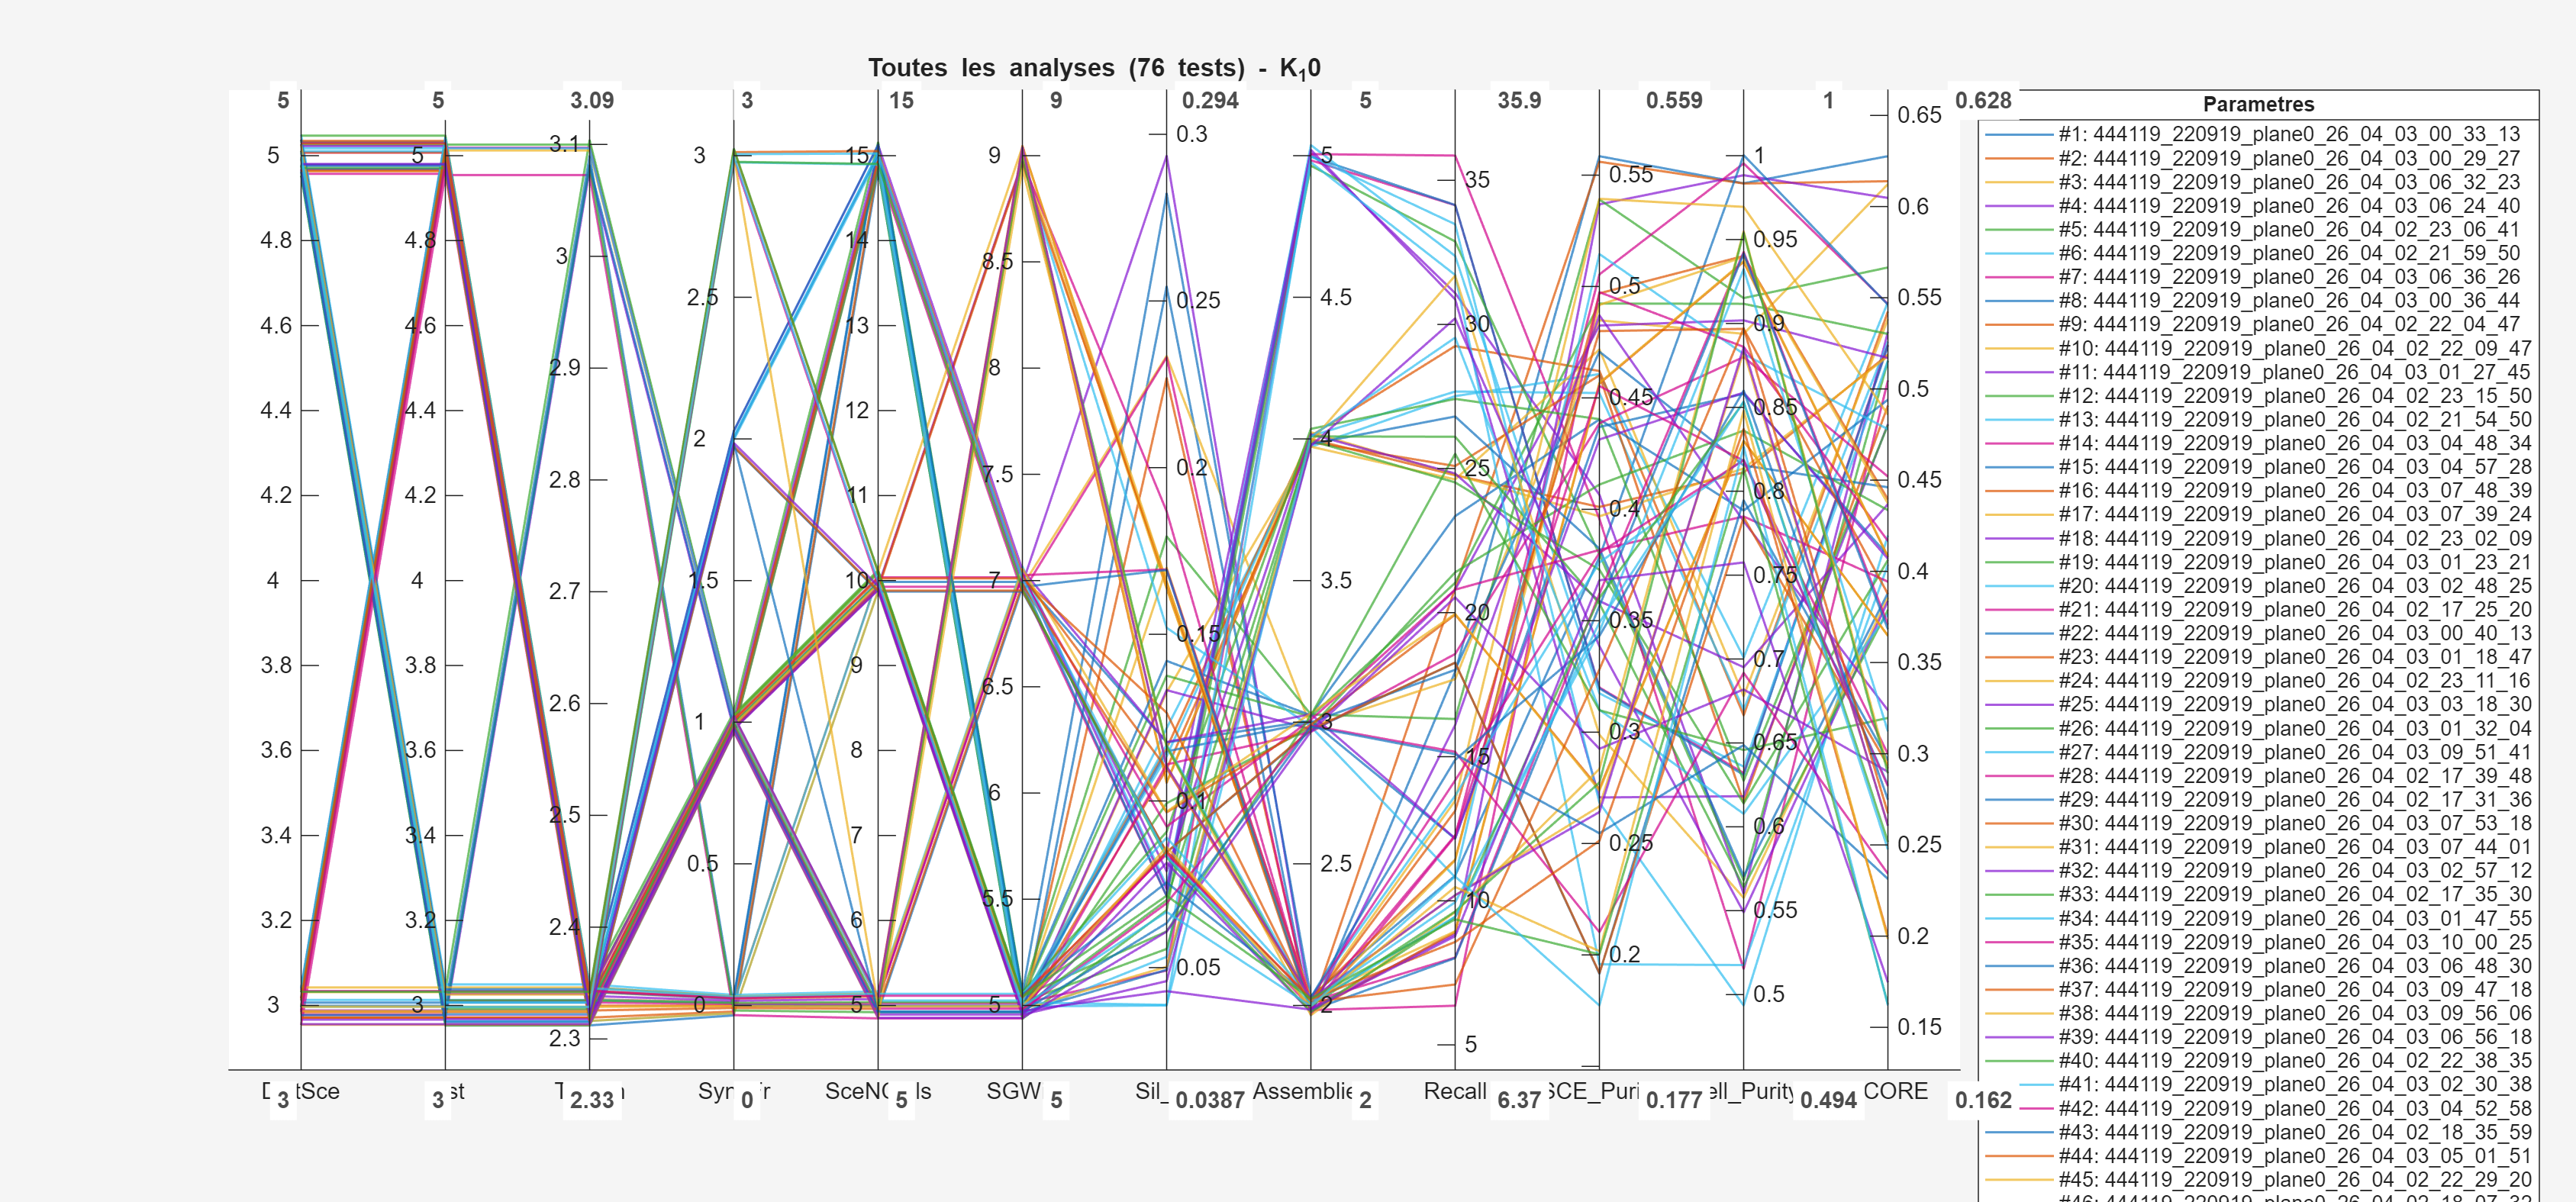

 ⭐ #1 -> 444119_220919_plane0_26_04_03_00_33_13 (Score: 0.63)
 ⭐ #2 -> 444119_220919_plane0_26_04_03_00_29_27 (Score: 0.61)
 ⭐ #3 -> 444119_220919_plane0_26_04_03_06_32_23 (Score: 0.61)


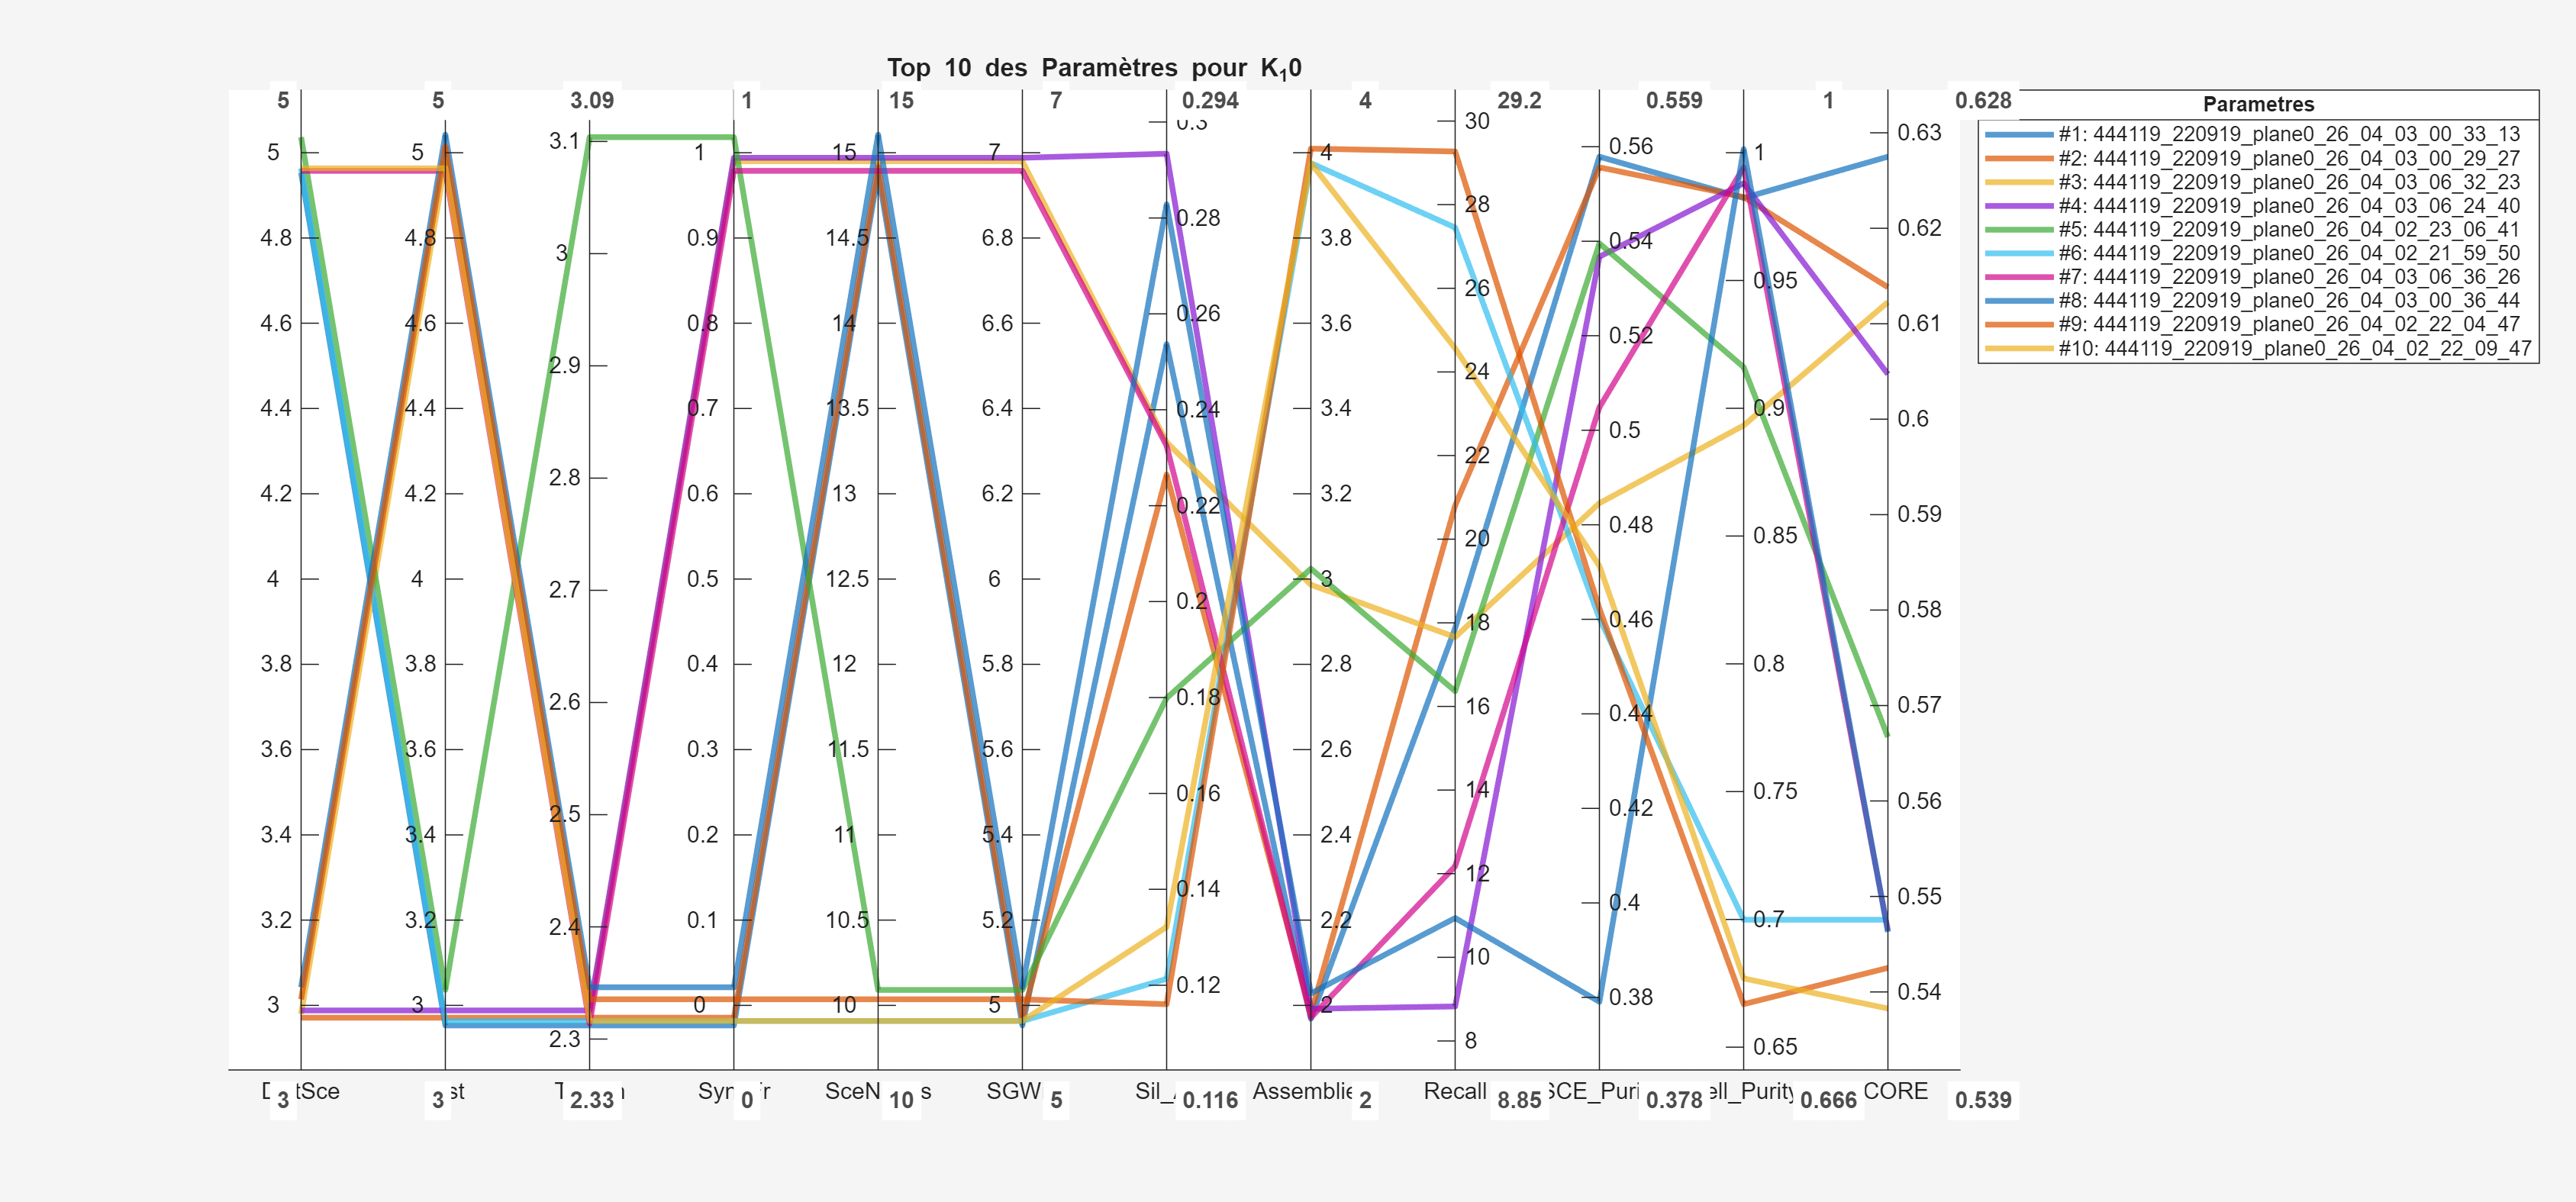

ANALYSE POUR K_15 (71 tests analysés)


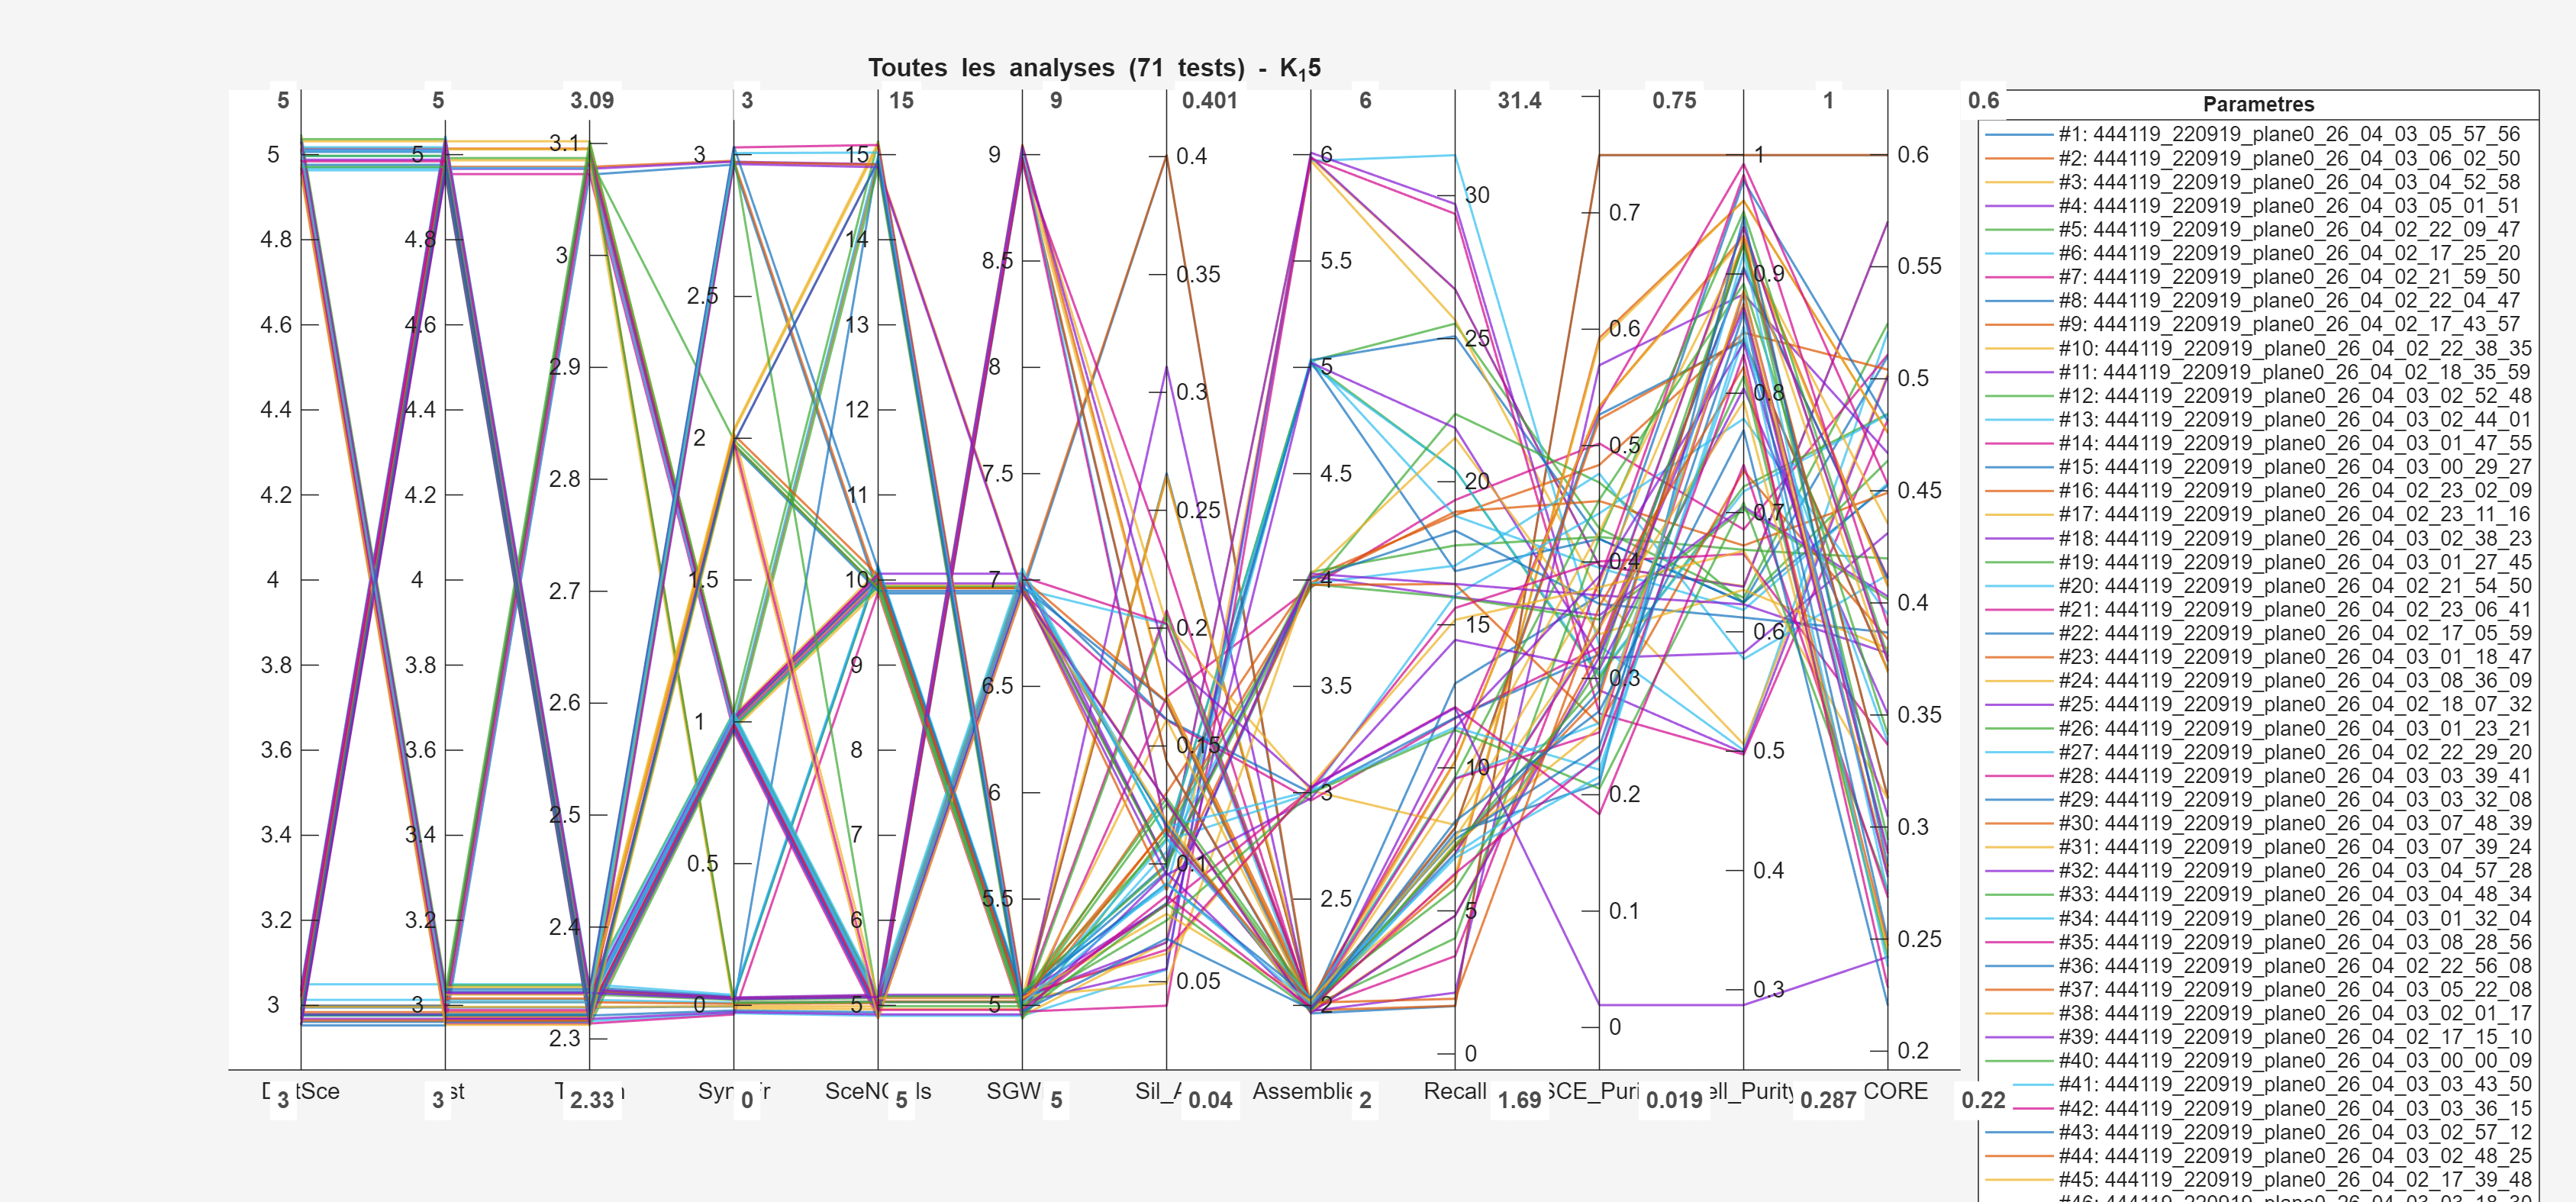

 ⭐ #1 -> 444119_220919_plane0_26_04_03_05_57_56 (Score: 0.60)
 ⭐ #2 -> 444119_220919_plane0_26_04_03_06_02_50 (Score: 0.60)
 ⭐ #3 -> 444119_220919_plane0_26_04_03_04_52_58 (Score: 0.57)


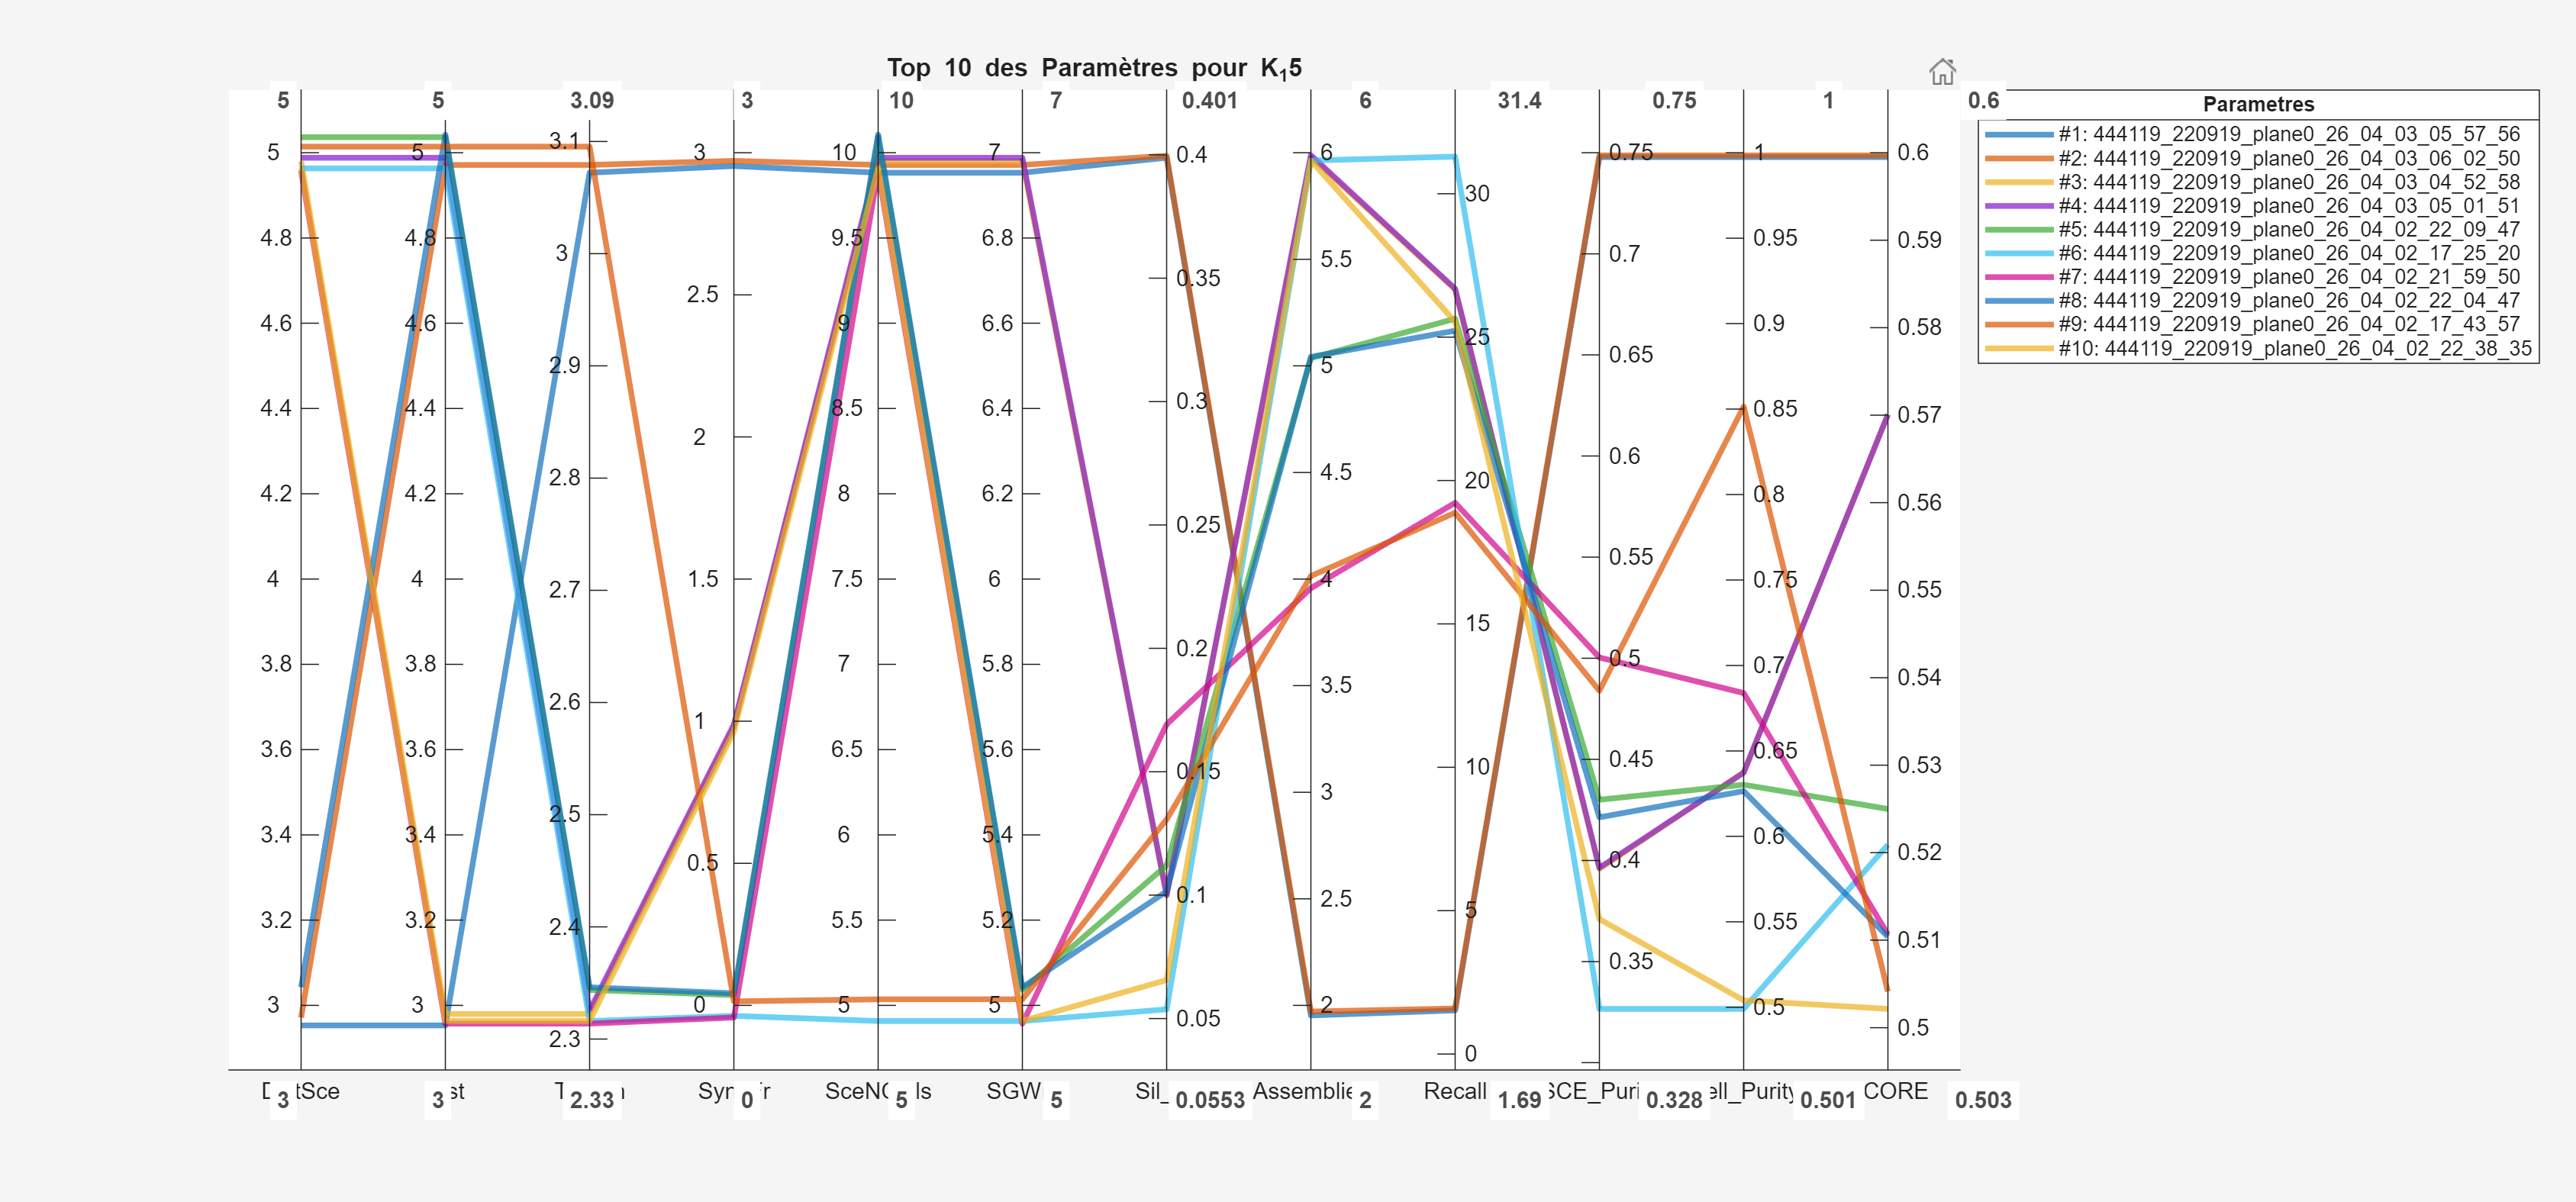

ANALYSE POUR K_5 (107 tests analysés)


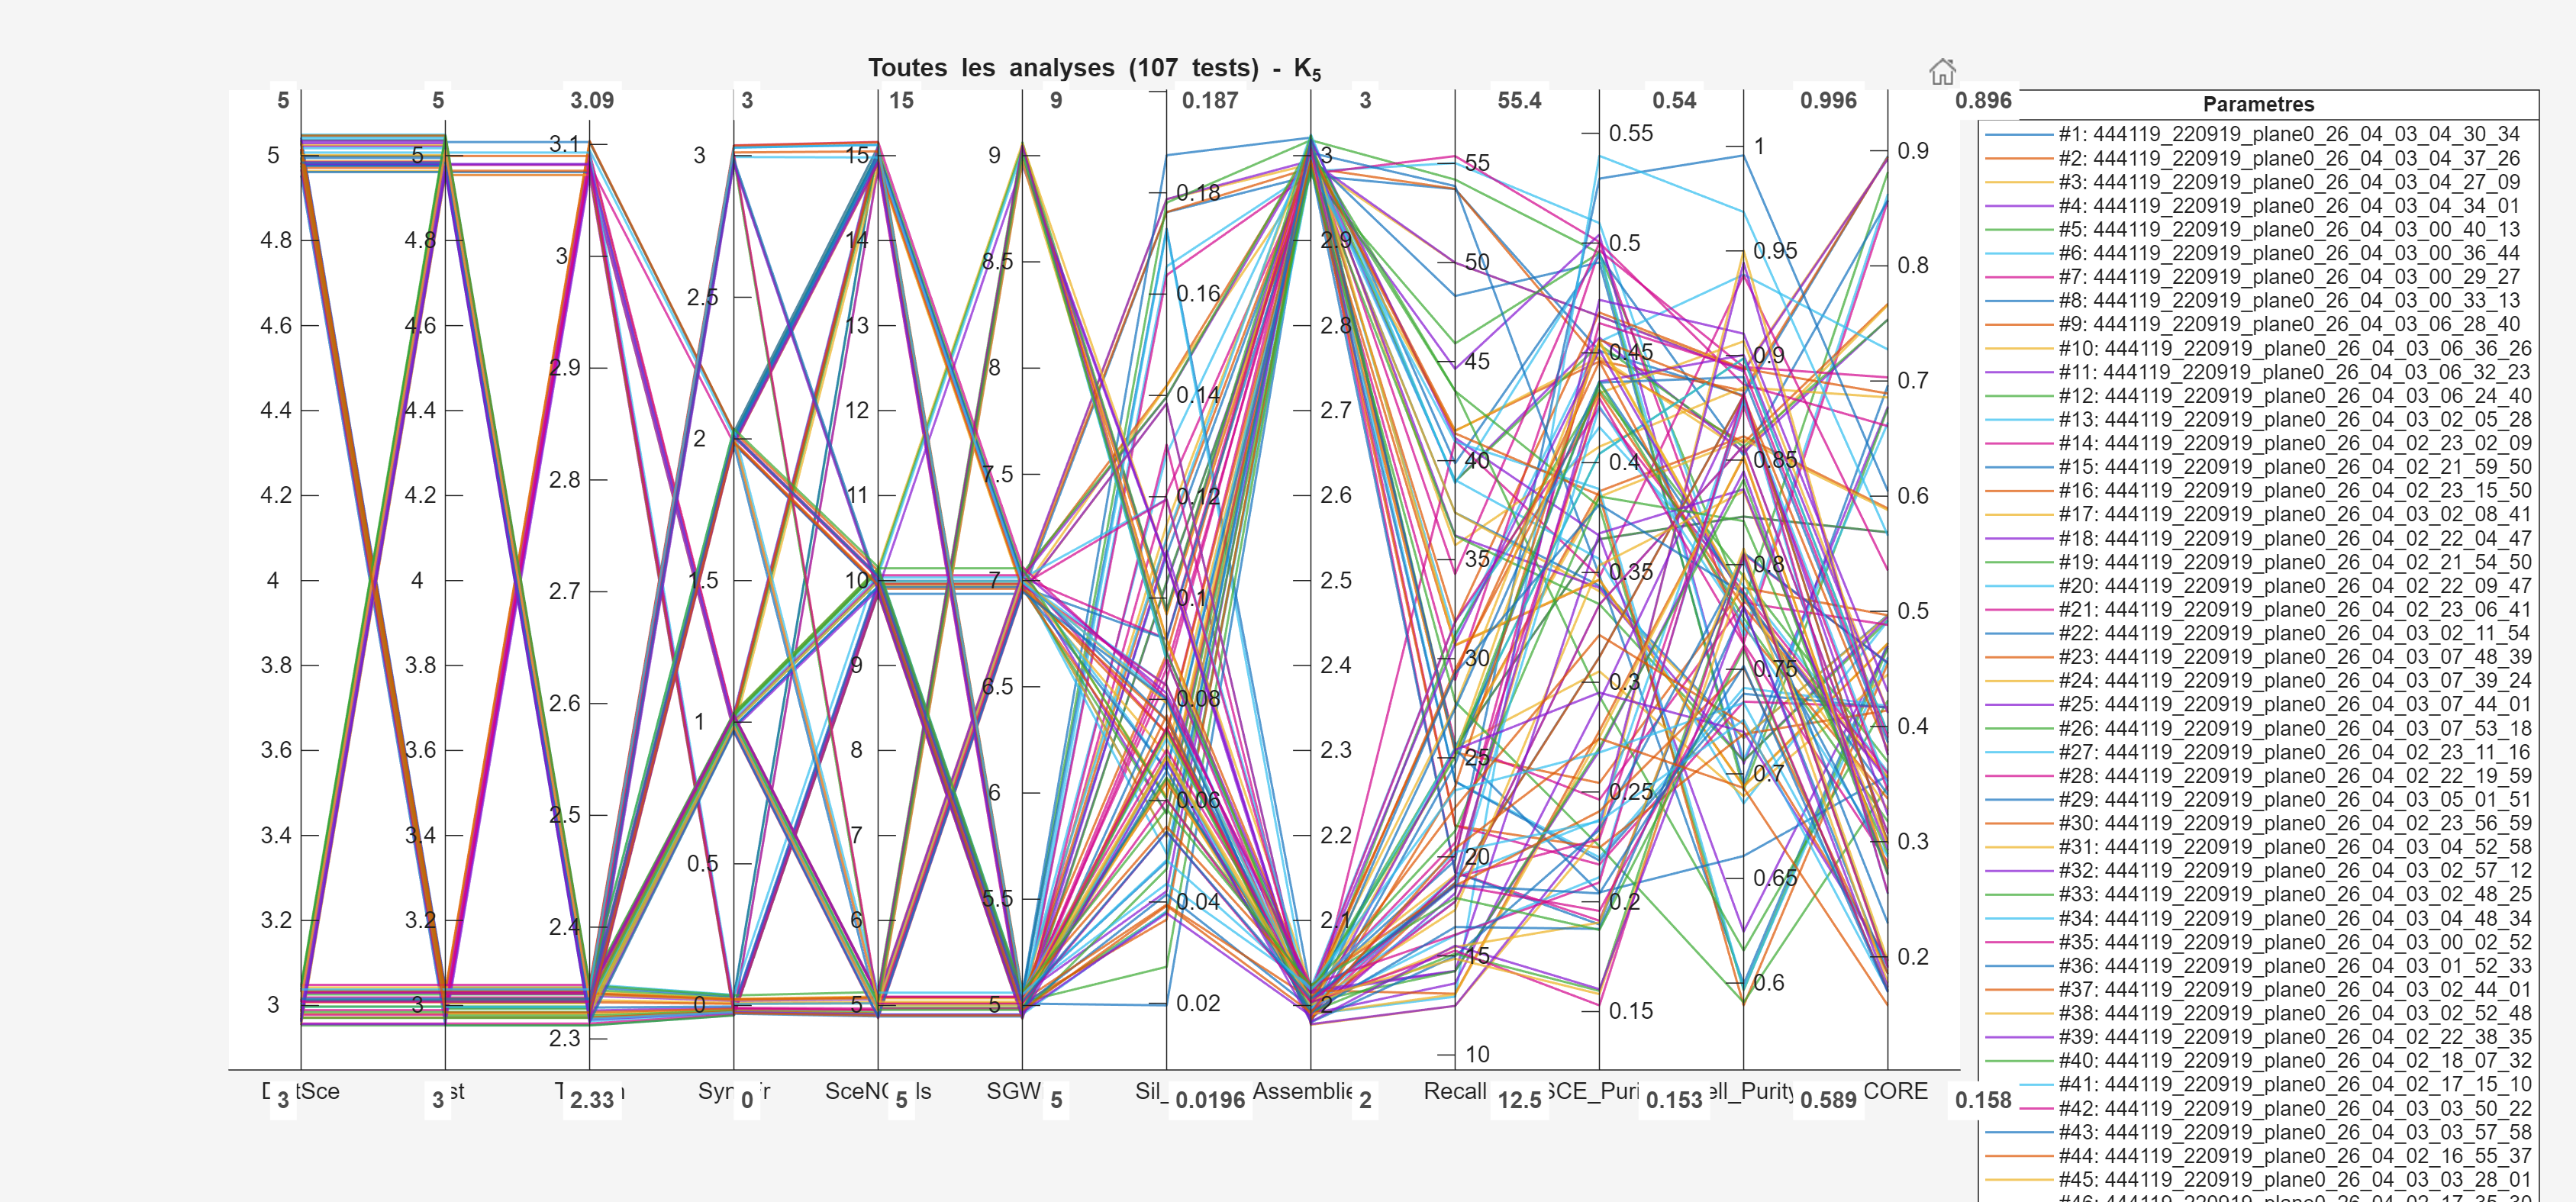

 ⭐ #1 -> 444119_220919_plane0_26_04_03_04_30_34 (Score: 0.90)
 ⭐ #2 -> 444119_220919_plane0_26_04_03_04_37_26 (Score: 0.89)
 ⭐ #3 -> 444119_220919_plane0_26_04_03_04_27_09 (Score: 0.89)


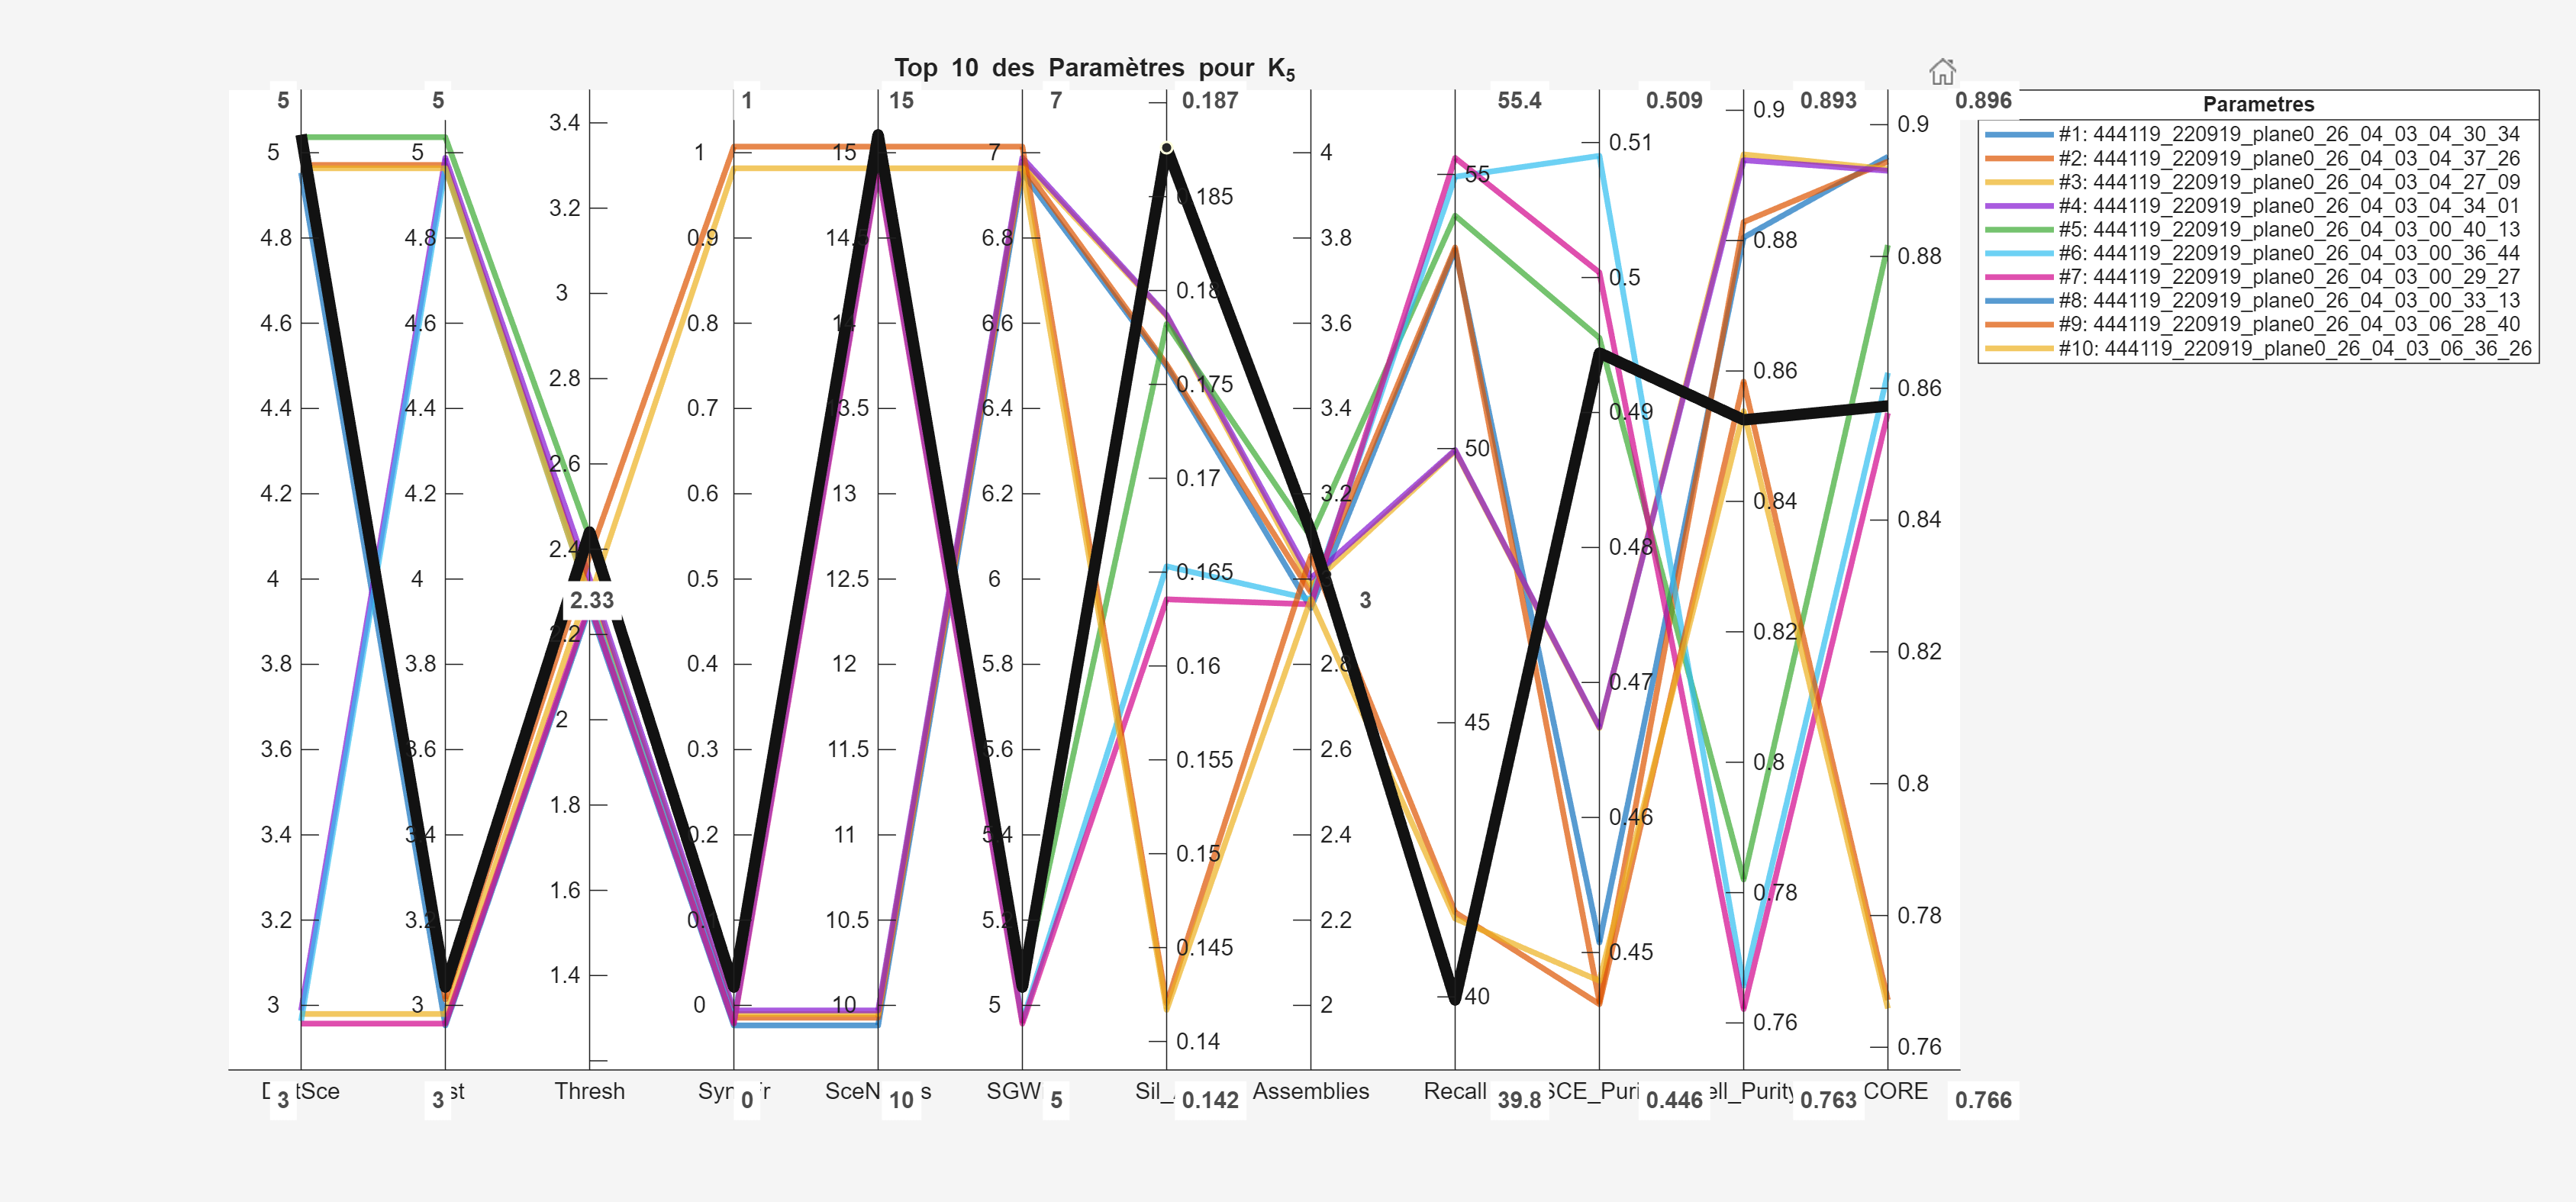

close(h_wait);

%% 5. CALCUL DES SCORES, EXCEL ET GRAPHIQUES
k_fields = fieldnames(ResultsByK);
varNamesGraph = {'DistSce', 'Dist', 'Thresh', 'SyncFr', 'SceNCells', 'SGWin', ...
                 'Sil_All', 'Assemblies', 'Recall', 'SCE_Purity', 'Cell_Purity', 'SCORE'};

for k_idx = 1:length(k_fields)
    curr_k_name = k_fields{k_idx};
    curr_data = ResultsByK.(curr_k_name);
    nb_tests = length(curr_data.sil_all_clusters);
    
    if nb_tests < 2
        fprintf('⚠️ Pas assez de tests pour %s, on passe.\n', curr_k_name);
        continue;
    end
    
    fprintf('\n==================================================\n');
    fprintf('ANALYSE POUR %s (%d tests analysés)\n', curr_k_name, nb_tests);
    fprintf('==================================================\n');
    
    % --- Score Composite ---
    norm_sil   = normalize_metric(curr_data.sil_all_clusters, 'maximize');
    norm_assem = normalize_metric(curr_data.Assemblies, 'maximize');
    norm_rec   = normalize_metric(curr_data.recall, 'maximize');
    norm_sce   = normalize_metric(curr_data.SCE_Purity, 'maximize');
    norm_cell  = normalize_metric(curr_data.cell_Purity, 'maximize');
    
    Scores = (w_sil * norm_sil) + (w_assemblies * norm_assem) + ...
             (w_recall * norm_rec) + (w_sce * norm_sce) + (w_cell * norm_cell);
    [sortedScores, sortIdx] = sort(Scores, 'descend');
    
    % --- EXCEL PREPARATION ---
    Ex_Param = curr_data.ParamFolder(sortIdx)'; Ex_Rang = (1:nb_tests)'; Ex_Score = sortedScores(:);
    Ex_DistSce = curr_data.DistSce(sortIdx)'; Ex_Dist = curr_data.Dist(sortIdx)'; Ex_Thresh = curr_data.Thresh(sortIdx)';
    Ex_Sync = curr_data.Sync(sortIdx)'; Ex_SceN = curr_data.SceNCells(sortIdx)'; Ex_SG = curr_data.SGWin(sortIdx)';
    Ex_Sil = curr_data.sil_all_clusters(sortIdx)'; Ex_Assem = curr_data.Assemblies(sortIdx)'; Ex_Rec = curr_data.recall(sortIdx)';
    Ex_Sce = curr_data.SCE_Purity(sortIdx)'; Ex_Cell = curr_data.cell_Purity(sortIdx)'; Ex_Path = curr_data.Paths(sortIdx)';
    
    % =====================================================================
    % DONNÉES POUR LE GRAPHIQUE "ALL" (Toutes les analyses)
    % =====================================================================
    Plot_Data_All = zeros(nb_tests, 12);
    Group_Labels_All = cell(nb_tests, 1);
    for i = 1:nb_tests
        Plot_Data_All(i, :) = [Ex_DistSce(i), Ex_Dist(i), Ex_Thresh(i), Ex_Sync(i), Ex_SceN(i), Ex_SG(i), ...
                               Ex_Sil(i), Ex_Assem(i), Ex_Rec(i), Ex_Sce(i), Ex_Cell(i), Ex_Score(i)];
        Group_Labels_All{i} = sprintf('#%d: %s', i, Ex_Param{i});
    end
    
    title_all = sprintf('Toutes les analyses (%d tests) - %s', nb_tests, curr_k_name);
    save_path_all = fullfile(dossier_mere, sprintf('ParallelPlot_Params_%s_ALL.png', curr_k_name));
    
    generer_graphique_parallele(Plot_Data_All, Group_Labels_All, varNamesGraph, title_all, save_path_all, 1.0); % Lignes fines
    
    % =====================================================================
    % DONNÉES POUR LE GRAPHIQUE "TOP N" (Les 10 meilleures)
    % =====================================================================
    n_plot = min(top_n_plot, nb_tests);
    Plot_Data_Top = Plot_Data_All(1:n_plot, :);
    Group_Labels_Top = Group_Labels_All(1:n_plot);
    
    for i = 1:n_plot
        if i <= 3, fprintf(' ⭐ #%d -> %s (Score: %.2f)\n', i, Ex_Param{i}, Ex_Score(i)); end
    end
    
    title_top = sprintf('Top %d des Paramètres pour %s', n_plot, curr_k_name);
    save_path_top = fullfile(dossier_mere, sprintf('ParallelPlot_Params_%s_TOP%d.png', curr_k_name, n_plot));
    
    generer_graphique_parallele(Plot_Data_Top, Group_Labels_Top, varNamesGraph, title_top, save_path_top, 2.5); % Lignes épaisses

    % --- SAUVEGARDE EXCEL ---
    TableFinal = table(Ex_Param, Ex_Rang, Ex_Score, ...
        Ex_DistSce, Ex_Dist, Ex_Thresh, Ex_Sync, Ex_SceN, Ex_SG, ...
        Ex_Sil, Ex_Assem, Ex_Rec, Ex_Sce, Ex_Cell, Ex_Path, ...
        'VariableNames', {'Dossier_Test', 'Rang', 'Score_Global', ...
        'P_DistSce', 'P_Dist', 'P_Threshold', 'P_SyncFrames', 'P_SceThreshold', 'P_SGWin', ...
        'M_sil_all_clusters', 'M_Assemblies', 'M_recall', 'M_SCE_Purity', 'M_cell_Purity', 'Chemin_Dossier'});
        
    excel_name = fullfile(dossier_mere, sprintf('Resume_Parametres_%s.xlsx', curr_k_name));
    writetable(TableFinal, excel_name);
end

fprintf('\n================ TOUTES LES ANALYSES SONT TERMINÉES ================\n');


================ TOUTES LES ANALYSES SONT TERMINÉES ================



% =========================================================================
% FONCTIONS LOCALES
% =========================================================================

function generer_graphique_parallele(Plot_Data, Group_Labels, varNames, title_str, save_path, line_width)
    % Cette fonction crée le Parallel Plot, ajoute les labels Min/Max et sauvegarde
    
    T_graph = array2table(Plot_Data, 'VariableNames', varNames);
    % On force l'ordre catégoriel pour que la légende respecte le classement
    T_graph.Parametres = categorical(Group_Labels, Group_Labels);
    
    fig = figure('Visible', 'on', 'Position', [50 100 1500 700]);
    
    % EXCLUSION DE LA COLONNE TEXTE DES AXES VIA 'CoordinateVariables'
    p = parallelplot(T_graph, 'CoordinateVariables', varNames, ...
                     'GroupVariable', 'Parametres', 'DataNormalization', 'range');
                 
    p.Title = title_str;
    p.LineWidth = line_width; 
    
    drawnow; % Obligatoire pour que MATLAB calcule le rendu avant d'ajouter le texte
    
    % Ajout de l'axe transparent pour le texte
    ax_text = axes('Position', [0.08 0.1 0.72 0.8], 'Visible', 'off'); 
    hold(ax_text, 'on');
    xlim(ax_text, [0.5, 12.5]); 
    ylim(ax_text, [0, 1]);
    
    min_vals = min(Plot_Data, [], 1);
    max_vals = max(Plot_Data, [], 1);
    
    for j = 1:12
        if max_vals(j) == min_vals(j)
            text(ax_text, j, 0.5, num2str(max_vals(j), '%.3g'), 'HorizontalAlignment', 'center', ...
                 'FontWeight', 'bold', 'FontSize', 10, 'Color', [0.3 0.3 0.3], 'BackgroundColor', 'w');
        else
            text(ax_text, j, 1.02, num2str(max_vals(j), '%.3g'), 'HorizontalAlignment', 'center', ...
                 'FontWeight', 'bold', 'FontSize', 10, 'Color', [0.3 0.3 0.3], 'BackgroundColor', 'w');
            text(ax_text, j, -0.02, num2str(min_vals(j), '%.3g'), 'HorizontalAlignment', 'center', ...
                 'FontWeight', 'bold', 'FontSize', 10, 'Color', [0.3 0.3 0.3], 'BackgroundColor', 'w');
        end
    end
    
    saveas(fig, save_path);
end

function norm_val = normalize_metric(val_array, direction)
    val_array = val_array(:); 
    min_v = min(val_array); max_v = max(val_array);
    if max_v == min_v, norm_val = ones(size(val_array)); return; end
    if strcmp(direction, 'maximize')
        norm_val = (val_array - min_v) ./ (max_v - min_v);
    elseif strcmp(direction, 'minimize')
        norm_val = (max_v - val_array) ./ (max_v - min_v);
    end
end